Stabilità

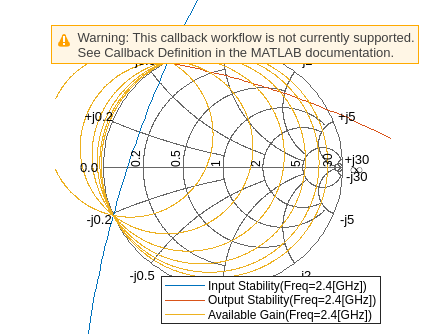

clear
clf

q_point = [8e-3 3]; %Ic VCE
op_freq = 2.4e9;
lin_freq = 3e7:10e6:5e9;

Z0=50; %ohm

bfp640 = read(rfckt.amplifier , 'BFP640/BFP640_w_noise_VCE_3.0V_IC_8.0mA.s2p');
[s_par , freq] = extract(bfp640 , 'S_parameters');


hsm = smithplot;
circle(bfp640,op_freq,'Stab','In','Stab','Out','Ga',10:2:20,hsm);
legend('Location','SouthEast')

gammas = 0.424-0.262i

gammas = 0.4240 - 0.2620i

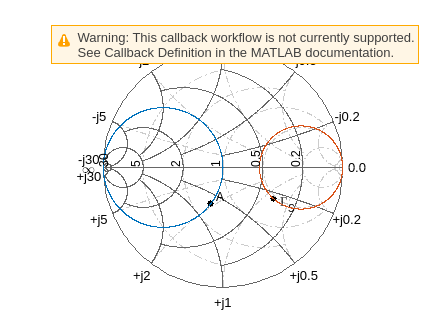


figure
sp = smithplot;
sp.GridType = 'YZ';

Za = (0.685-0.453j)*Z0;

circle(bfp640 , op_freq , "G" , 1 , "R", real(gamma2z(gammas , 1)) , sp);
hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Za),'k.','MarkerSize',16);
text(real(z2gamma(Za))+0.05,imag(z2gamma(Za))+0.05,'A','FontSize', 12, ...
    'FontUnits','normalized');
hold off

imag(Za)

ans = -22.6500

C_shunt = imag(1/Za)/(2*pi*op_freq)

C_shunt = 8.9084e-13

C_series = 1/(2*pi*op_freq*abs(imag(gamma2z(gammas) - Za)))

C_series = 1.5501e-12


% C_shunt = 600e-15
% C_series = 2.55e-9

input_match = rfckt.cascade('Ckts', ...
    {rfckt.shuntrlc('C',C_shunt),rfckt.seriesrlc('C',C_series)});

Output match

gammal = 0.196+0.075i

gammal = 0.1960 + 0.0750i


figure
sp2 = smithplot;
sp2.GridType = 'YZ';


Zb = (1+0.706j)*Z0

Zb = 50.0000 + 50.3500i

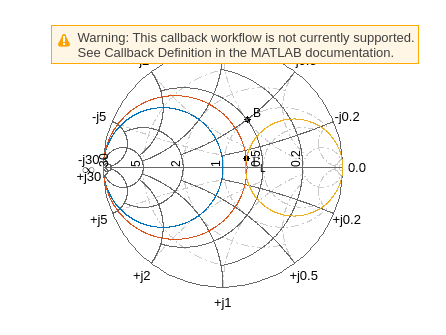


circle(bfp640 , op_freq , "G" , 1 , "G" , real(1/gamma2z(gammal , 1)) , "R", real(gamma2z(gammal , 1)) , sp2);
hold on
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Zb),'k.','MarkerSize',16);
text(real(z2gamma(Zb))+0.05,imag(z2gamma(Zb))+0.05,'B','FontSize', 12, ...
    'FontUnits','normalized');

hold off

imag(gamma2z(gammal,1) - Zb/50)

ans = -0.7770

L_shunt = (abs(imag(1/gamma2z(gammal,1) - 1/Zb))/(2*pi*op_freq))/50

L_shunt = 1.2527e-13

L_series = abs(imag(Zb))/(2*pi*op_freq)

L_series = 3.3389e-09


% L_shunt = 27e-9
% L_series = 2.55e-9

output_match = rfckt.cascade('Ckts', ...
  {rfckt.shuntrlc('C',L_shunt),rfckt.seriesrlc('L',L_series)});

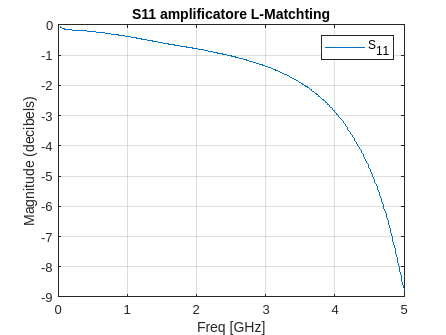

LNA = rfckt.cascade('ckts', ...
    {input_match,bfp640,output_match});

analyze(LNA,lin_freq);

LNA_sper = read(rfckt.amplifier , 'L_NO_COP.s2p');
analyze(LNA_sper,lin_freq);

figure,plot(LNA,'S11','dB');
title("S11 amplificatore L-Matchting")
hold on
%plot(LNA_sper,'S11','dB');
hold off

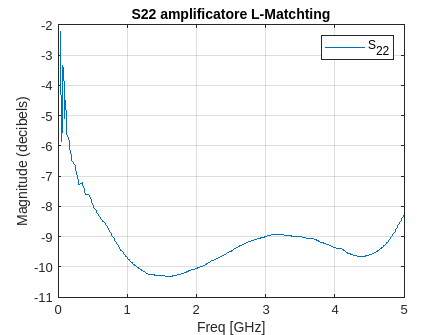


figure,plot(LNA,'S22','dB');
title("S22 amplificatore L-Matching")
hold on
%plot(LNA_sper,'S22','dB');
hold off

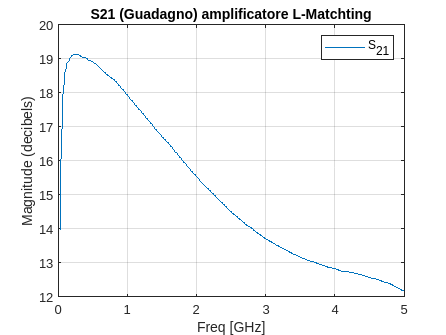


figure,plot(LNA,'S21','dB');
title("S21 (Guadagno) amplificatore L-Matchting")
hold on
%plot(LNA_sper,'S21','dB');
hold off